# Area vs time modeling

load('Data\MeanData\MeanBinnedData.mat','S','M','t','varNames')

Plot fArea vs time

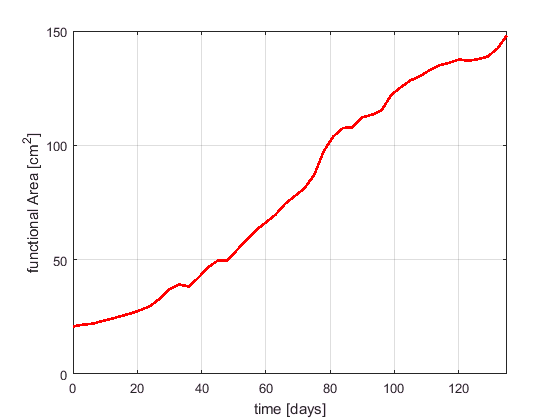

t0 = find(t==0); tend = find(t==135);
t1 = t(t0:tend);
A = M(1).Mean(t0:tend);
figure
plot(t1,A,'r','LineWidth',2)
xlim([0 135])
ylim([0 150])
xlabel('time [days]')
ylabel('functional Area [cm^2]')
grid on

Model

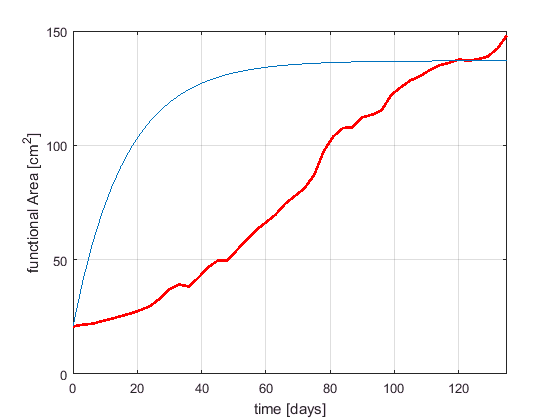

F = @(A0,As,a,t) (A0-As).*exp(-a.*t./As)+As;
A0 = A(1);
As = 137; 
a = max(gradient(A));
Am = F(A0,As,a,t1);

hold on
plot(t1,Am)

Verhulst model

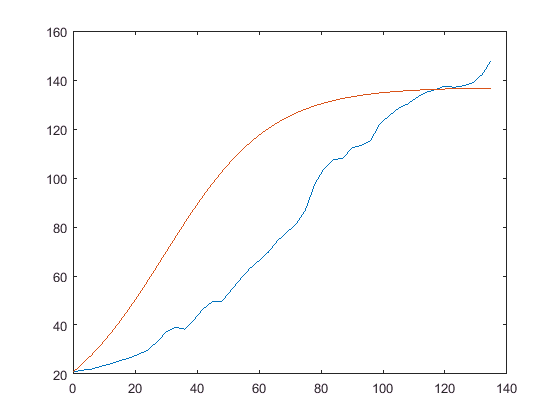

V = @(A0,As,a,t) As./(1+((As./A0)-1).*exp(-a.*t));
A0 = A(1);
As = 137;

[maxRate,maxIdx] = max(gradient(A));
Half_idx = find(A>=As./2,1);
gradA = gradient(A);
a = gradA(Half_idx)./A(Half_idx);

AV = V(A0,As,a,t1);

figure
plot(t1,A,t1,AV)

Bad fit

try finding best fit for parameter "a"

from curve fitting tool get; a= 0.033

play around a bit more with As and a, use As = 160, a = 0.03, get even better fit

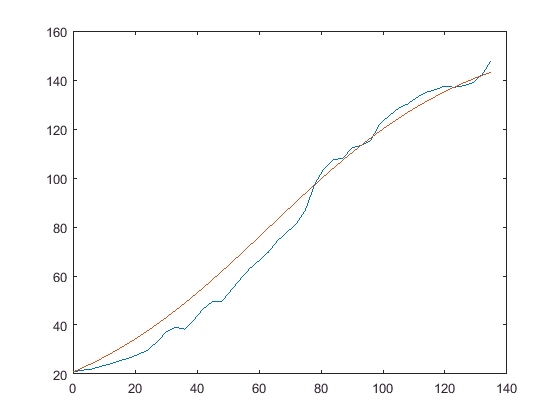

AV = V(A0,160,0.03,t1);

figure
plot(t1,A,t1,AV)

Gradient plot

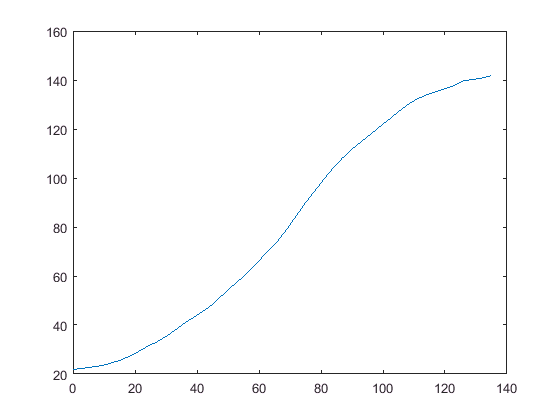

smoothA = movmean(A,7);
gradA = gradient(smoothA);
plot(t1,smoothA)

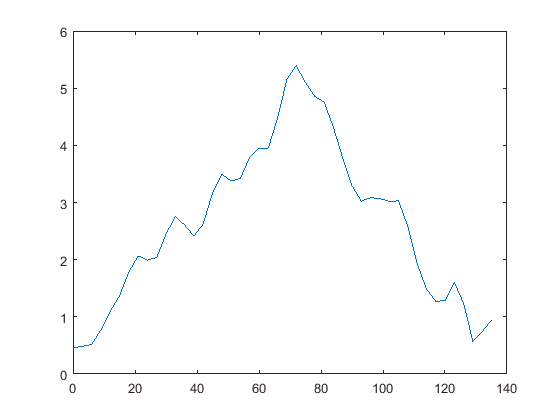

figure
plot(t1,gradA)